# (c) NEWTON METHOD

f = @(x) (x^2 + x^3);
% x_(n+1) = x_(n)  -  f'(x_n)/f''(x_n)  
f1 = @(x) 3*x^2  + 2*x;  % first derivative
f2 = @(x) 6*x + 2;   % second derivative
x = 0.1; % inntial guess
xx(1) = x;
err = 0.01; % tolerance
N= 100 ; % number of Iterations
for i = 1:N
    x =x - f1(x)/f2(x) ;
    j = i +1 ;
    xx(j) = x; ii = i;
    Err = abs(xx(j) - xx(j-1));  
    if Err<err , break 
    end
end
    FF = f(x);
    disp(['The Mininum Value at : ' num2str(x) ', is: ' num2str(FF) ', No of Iterations: ' num2str(ii)])

The Mininum Value at : 5.5854e-08, is: 3.1197e-15, No of Iterations: 3


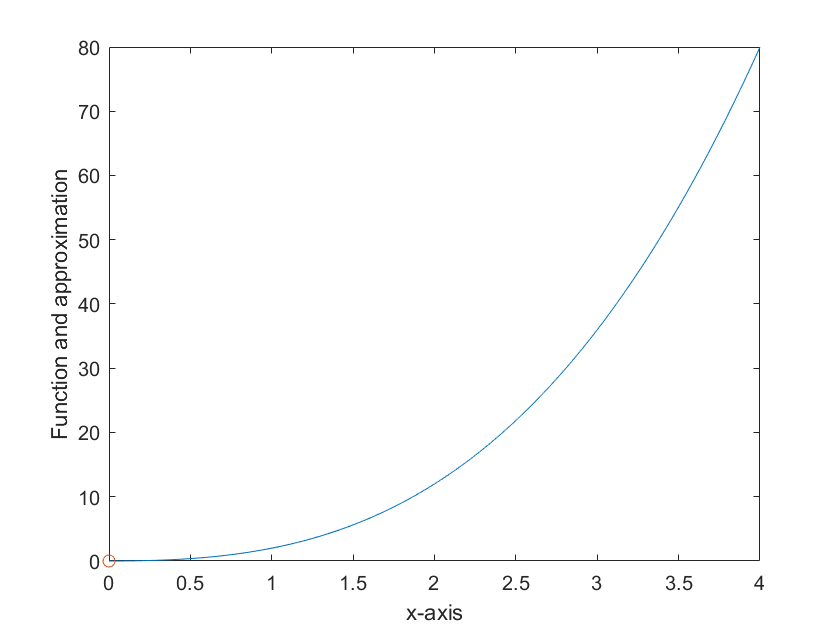

    xvalues = 0:0.01:4;
    F = xvalues.^2 + xvalues.^3 ;
    plot(xvalues,F);  % plot the given function
    hold on 
    plot(x,FF,"o")
    xlabel("x-axis")
    ylabel("Function and approximation")